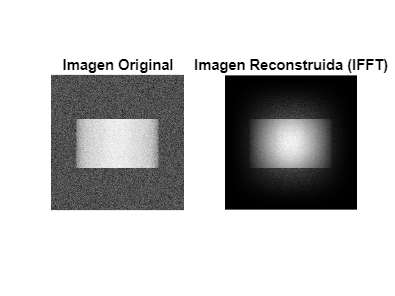

% Lee la imagen
imagen = imread('Fourier2.jpg');

% Convierte la imagen a escala de grises si es a color
if size(imagen, 3) == 3
    imagen_gris = rgb2gray(imagen);
else
    imagen_gris = imagen;
end

% Obtiene el tamaño de la imagen
[m, n] = size(imagen_gris);

% Crea la ventana de Hann en ambas direcciones (filas y columnas)
ventana_hann = hann(m) * hann(n)';

% Aplica la ventana de Hann a la imagen
imagen_hann = double(imagen_gris) .* ventana_hann;

% Calcula la FFT de la imagen con ventana de Hann
imagen_fft = fft2(imagen_hann);

% Calcula la IFFT de la imagen FFT
imagen_ifft = ifft2(imagen_fft);

% Muestra la imagen original y la imagen reconstruida
figure;
subplot(1, 2, 1);
imshow(imagen_gris, []);
title('Imagen Original');

subplot(1, 2, 2);
imshow(abs(imagen_ifft), []);
title('Imagen Reconstruida (IFFT)');